## VDC vs output voltage

VDC = [0 2.35]; % VDC values
Vout = [50 100]; % Output voltage values

figure; % Create a new figure
plot(VDC, Vout, '-'); % Plot the line
xlabel('Input Voltage VADJ (V)'); % Label the x-axis
ylabel('Output Voltage VP(V)'); % Label the y-axis
title('Input Voltage VADJ vs Output Voltage VP'); % Title the plot
grid on; % Turn on the grid

## Resistance vs output voltage

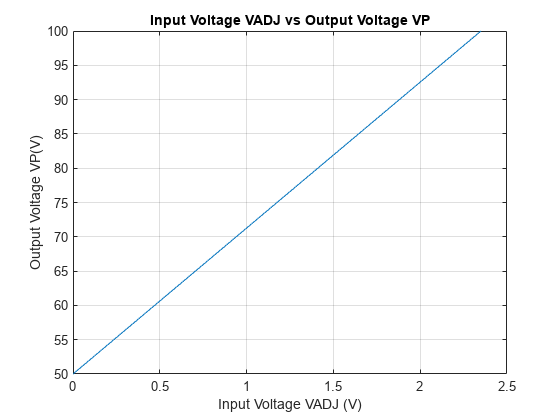

R = [0 4125]; % VDC values
Vout = [50 120.1]; % Output voltage values


figure; % Create a new figure
plot(R, Vout, '-'); % Plot the line
xlabel('Resistance (Ohm)'); % Label the x-axis
ylabel('Output Voltage (V)'); % Label the y-axis
title('Resistance vs Output Voltage'); % Title the plot
grid on; % Turn on the grid

## Plot Vp(t) for both charging and discharging

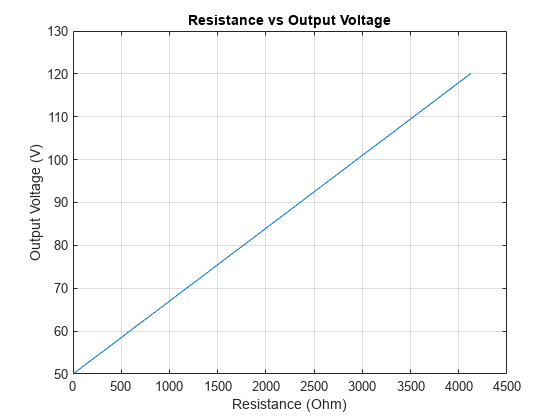


% Given parameters
C_p = 1e-6;          % Capacitance in farads (1 microfarad)

R_p = 0.1;           % Resistance in ohms (0.1 ohm)
V = 100;             % Peak Voltage in volts

% Calculate the time constant and the max time to display
tau = R_p * C_p;     % Time constant
max_time_to_display = tau * 6 * 2;

% Create a time vector for both charging and discharging with discontinuity at the midpoint
t_total = linspace(0, max_time_to_display, 2000);   % Time vector for charging and discharging

% Calculate Vp(t) across the total timeframe
Vp_total = [V * (1 - exp(-t_total(1:1000) / tau)), ...
            V * exp(-(t_total(1001:end) - t_total(1001)) / tau)];

% Plot the voltage over time
figure; % Create new figure window
plot(t_total * 1e6, Vp_total, 'b'); % Multiply by 1e6 to convert to microseconds
            
% Annotations for "Charging" and "Discharging"
charging_time = tau * 1e6; % Convert to microseconds for placement
discharging_time = charging_time * 8; % Convert to microseconds for placement
text(charging_time, V / 2, 'Piezo on', 'HorizontalAlignment', 'center');
text(discharging_time, V / 2, 'Piezo off', 'HorizontalAlignment', 'center');

title('Voltage across Piezo during Charging and Discharging'); 
xlabel('Time (μs)'); % 'u' was changed to the proper micro sign 'μ'
ylabel('Voltage (V)');
grid on; % Add grid for better readability

## Window comparator

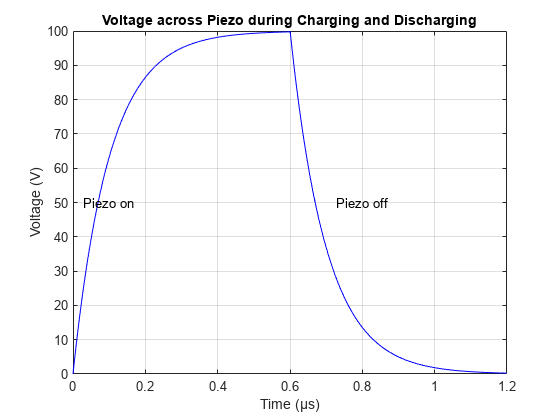

% Define the time vector
t = 0:0.001:1; % time from 0 to 1 second in milliseconds

% Create an example falling voltage signal
V_in = linspace(0.05, -0.15, length(t)); % Start at 50mV, end at -150mV

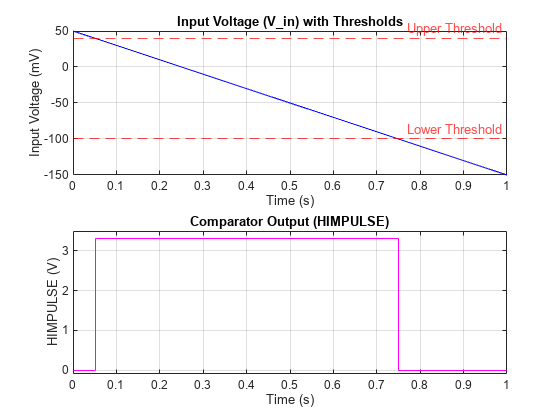


% Define the upper and lower thresholds of the window comparator
V_upper = 0.04;  % Upper threshold at +40mV
V_lower = -0.10; % Lower threshold at -100mV

% Initialize the HIMPULSE signal with an amplitude of 3.3V
HIMPULSE = zeros(size(V_in)); % Initialize HIMPULSE

% Process the input voltage through the window comparator logic
for i = 1:length(V_in)
    if V_in(i) > V_lower && V_in(i) < V_upper
        HIMPULSE(i) = 3.3; % Signal is within the window, output HIGH
    end
    % Else, HIMPULSE remains at 0V
end

% Plot the input voltage and include the threshold lines
figure;
subplot(2,1,1); % First subplot for input voltage
plot(t, V_in*1000, 'b'); % Plot V_in in mV
hold on;
yline(V_upper*1000, 'r--', 'Upper Threshold');
yline(V_lower*1000, 'r--', 'Lower Threshold');
hold off;
xlabel('Time (s)');
ylabel('Input Voltage (mV)');
title('Input Voltage (V\_in) with Thresholds');
grid on;

% Second subplot for the HIMPULSE signal
subplot(2,1,2);
stairs(t, HIMPULSE, 'm'); % Use stairs to show HIMPULSE response
xlabel('Time (s)');
ylabel('HIMPULSE (V)');
title('Comparator Output (HIMPULSE)');
ylim([-0.1, 3.5]); % Extend y-axis to show the HIMPULSE level clearly
grid on;